clear 
close all
clc

**Model definition and data generation**

Given dataset y = a0+b0*x+c0*x^2+e

a_true = -2.923;
b_true = 7.18;
c_true = 2.8;

Number of data to generate:

N=100;

Input:

rng(1)
x = sort(randi([1, 50],N,1));
x_square=x.^2;

Noise:

noise_std = 12.8;
eG  = noise_std*randn(N,1);

Output:

y = a_true+b_true*x+c_true*x_square;

Noise corrupted output:

yn = y + eG;

**Identification**

Matrix H:

H1 = zeros(N,3);
for i=1:N
    H1(i,:) = [1 x(i) x_square(i)];
end

H2 = zeros(N,2);
for i=1:N
    H2(i,:) = [1 x(i)];
end


Theta = inv(H'H)H'y:

th1 = (H1'*H1)\H1'*yn;
a1hat = th1(1)

a1hat = 2.5289

b1hat = th1(2)

b1hat = 6.4412

c1hat= th1(3)

c1hat = 2.8151


th2 = (H2'*H2)\H2'*yn;
a2hat = th2(1)

a2hat = -1.1359e+03

b2hat = th2(2)

b2hat = 146.7885

ypred

y1pred = a1hat + b1hat*x +c1hat*x_square ;

y2pred = a2hat + b2hat*x;

Plot

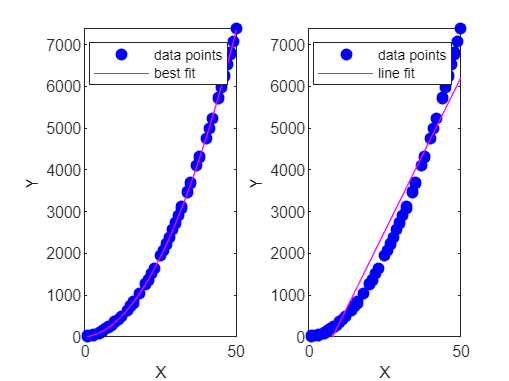

figure(1); clf;
subplot(1,2,1)
plot(x,yn,'bo',...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0,0,1])
hold on
plot(x,y1pred,'-m')
legend('data points','best fit')
xlabel('X')
ylabel('Y')
ylim([min(yn) max(yn)])

subplot(1,2,2)
plot(x,yn,'bo',...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0,0,1])
hold on
plot(x,y2pred,'-m')
legend('data points','line fit')
xlabel('X')
ylabel('Y')
ylim([min(yn) max(yn)])

The least-squares error with the true data

pred_error1=(rms(y-y1pred))^2;
disp(['Prediction error of polynomial is: ' num2str(pred_error1)])

Prediction error of polynomial is: 8.3508



pred_error2=(rms(y-y2pred))^2;
disp(['Prediction error of line is: ' num2str(pred_error2)])

Prediction error of line is: 282758.6138
